# Handleiding: MATLAB Live Scripts

## ***Overzicht belangrijkste commando's***

1. Algemene opmerkingen

- invoer van commando's  **alt + enter, clear all, vpa, ans**

- formatteren van output    **commando;**

**                                          commando, commando**

**                                          commando**

- help en bewaren  **help commando, doc commando**

- symbolische variabelen  **syms**

2. Expressies, functies en vergelijkingen

- hoe definiëren  **=, lhs, rhs, piecewise**

- ingebouwde functies en constanten  **abs(x), sqrt(x), exp(x), log(x), sin(x), ..., exp(inf), pi of sym('pi'), i of 1i of sym(i) of sym(1i), inf of sym('inf')**

- evalueren **subs**

- manipuleren van expressies  **factor, expand, combine, rewrite, simplify, coeffs, partfrac**

3. Basisbewerkingen

- oplossen van vergelijkingen en stelsels  **solve, vpasolve**

- limieten  **limit**

- afgeleiden  **diff**

- integralen  **int, vpaintegral**

- matrices en vectoren  [... ; ... ; ...], **zeros, ones, eye, diag, transpose **of** ', inverse **of** ^(-1), norm, dot, cross**

4. Beperkingen opleggen

- blijvende beperkingen **assume, assumeAlso, assumptions**

5. Tekeningen maken

- 2D-grafieken  **fplot, fimplicit, linspace, ylim, axis equal, **

- 3D-grafieken  **fplot3, fsurf, fimplicit3**

- contourplots  **fcontour**

- vectorvelden  **quiver, quiver3**

- andere nuttige commando's  **hold on, hold off, colorbar, LevelList,  MeshDensity**

6. Een beetje programmeren  **if ... else ... end,**

**                                                for i = ... : ... end,**

**                                                while ... end**

## **1. Algemene opmerkingen**

## ***Invoer van commando's en secties***

Een commando kan enkel ingegeven worden in een sectie, aangeduid met een grijs vak. Een vak kan toegevoegd worden met **alt+enter** en kan verwijderd worden met backspace om tekst te kunnen ingeven. 

Je kan meerdere commando's op eenzelfde regel ingeven, door de commando's te scheiden met komma **, **. Je kan ook een puntkomma **;** gebruiken, maar dit onderdrukt tegelijk de output van het voorafgaande commando.

Het is ook mogelijk meerdere regels binnen een executieblok in te geven, door gebruik te maken van **enter**. In dit geval hoeven de commando's niet afgesloten te worden met een komma of puntkomma. Alle commando's in eenzelfde executieblok zullen altijd allemaal uitgevoerd worden. 

Verschillende executieblokken kunnen worden gecombineerd door secties. Bij een druk op **ctrl+enter** ergens in de sectie, worden alle executieblokken in de volledige sectie uitgevoerd. Secties worden afgebakend door fijne horizontale grijze lijnen. De sectie waarin de cursor zich bevindt, zal afgebakend worden met fijne blauwe lijnen aan de linkerkant met een blauwe balk. Je kan de grens van een sectie toevoegen in het Live Editor-tabblad, onder het submenu Section -> Section Break. Een grens verwijderen kan door er achter te gaan staan met de cursor en **backspace **in te drukken.

Het kan van belang zijn waar je je secties precies definieert terwijl je in een document aan het werken bent. Het is mogelijk dat je in een vorige sectie een variabele toekent en die in een volgende sectie gebruikt. Als je in die laatste sectie aan de variabele een nieuwe waarde toekent, zal het opnieuw uitvoeren van enkel de laatste sectie een ander resultaat opleveren. Je kan dus best iedere oefening opsplitsen in afzonderlijke, onafhankelijke deelstappen.

Meerdere secties in een keer uitvoeren kan via het Section-menu in het Live Editor-tabblad. Dit stopt echter wel bij een Error.

clear all

Het commando  **clear all** wist het geheugen door de workspace leeg te maken. Het is aangeraden dit voor elke nieuwe oefening te doen. In de workspace (in het venster rechts) zie je alle variabelen die eerder zijn gedefinieerd en wat ze inhouden. 

## *Getallen en elementaire bewerkingen*

Eenvoudige berekeningen met getallen kunnen gewoon worden ingegeven. We worden hier al geconfronteerd met een belangrijk gegeven: MATLAB is fundamenteel een numeriek programma, wat betekent dat de standaardvoorstelling van getallen die van een kommagetal is, dat afgerond wordt na ongeveer 16 beduidende cijfers. Meestal willen we voor deze cursus exact rekenwerk uitvoeren, met *symbolische *in plaats van numerieke berekeningen. Dit moeten we specifiek vermelden met het commando **sym**.

2^2 + 3 * (6 - 2) + 1/3

ans = 16.3333

sym(2^2 + 3 * (6 - 2) + 1/3)

$$ans = \frac{49}{3}$$

Let wel op volgende vaak voorkomende fout bij het ingeven van vermenigvuldigingen. **Het maalteken**  *****  **moet expliciet ingegeven worden!**

% sym(2^2 + 3(5 - 2)) is fout
sym(2^2 + 3*(5 - 2))

$$ans = 13$$

Met **sym** probeert MATLAB afgeronde kommagetallen om te zetten naar symbolische uitdrukken. Het volgende commando loopt mis.

sym(1 / pi)

$$ans = \frac{5734161139222659}{18014398509481984}$$

De reden hiervoor is dat eerst $\frac{1}{\pi}$ uitgerekend (en afgerond) wordt, en dan probeert MATLAB dit te herkennen als een symbolische uitdrukking. Een oplossing is om het commando **sym **zo ver mogelijk naar binnen te schuiven.

1 / sym(pi)

$$ans = \frac{1}{\pi }$$

Omgekeerd: een symbolische uitdrukking kan numeriek benaderd worden door het commando **vpa** te gebruiken:

x = sym(5/16)

$$x = \frac{5}{16}$$

vpa(x)

$$ans = 0.3125$$

Met **ans **kan je eenvoudig verwijzen naar het laatst berekende resultaat. Let wel op: het laatst berekende antwoord is niets steeds het antwoord boven de huidige regel, want je kan ook middenin het document commando's opnieuw laten uitrekenen.

sym(1)

$$ans = 1$$

sym(2)

$$ans = 2$$

ans

$$ans = 2$$

Het imaginair getal i wordt in output voorgesteld met **i ** of **1i**. Wanneer de waarde van **i **eerder overschreven is, kan je steeds de uitdrukking **1i** gebruiken. Het is aangeraden om steeds deze optie te gebruiken om fouten te vermijden.

sym(sqrt(-1))

$$ans = \mathrm{i}$$

sym(i^2)

$$ans = -1$$

sym(1i^2)

$$ans = -1$$

## *Variabelen en symbolen*

Intussen kunnen we werken met concrete waarden. Als we ook willen rekenen met een symbool dat een parameter of een onbekende voorstelt, moeten we dat symbool eerst definiëren met het commando **syms**. Meerdere symbolen kunnen in één keer worden gedefinieerd door ze achter syms te scheiden met een spatie. Bijvoorbeeld:

syms a x

Nu kunnen we andere variabelen definiëren in termen van a en x:

y = a*x^2

$$y = a\,x^{2}$$

Met het commando **disp **kan je eenvoudig de waarde van een bepaalde variabele tonen.

disp(y)

$$a\,x^{2}$$

**Let op: als MATLAB een symbool tegenkomt dat nog geen concrete waarde gekregen heeft, en ook niet op voorhand aangegeven is met syms, zal het een foutmelding geven. **Hier forceren we een foutmelding, die we voorzichtig opvangen. Dit hoef je zelf niet te kunnen.

try
    disp(b) % We proberen b te gebruiken in een commando
catch foutmelding
    disp(getReport(foutmelding))
end

Unrecognized function or variable 'b'.

Error in LiveEditorEvaluationHelperE1164646650 (line 20)
    disp(b) % We proberen b te gebruiken in een commando

Error in matlab.internal.editor.evaluateRegions

Error in matlab.internal.editor.EvaluationOutputsService.evalRegions


## ***Formatteren van output***

Wanneer een variabele met als naam een Griekse letter (bv. **alpha**, **beta**, ....) wordt gedefinieerd als een symbool, wordt deze in de output weergegeven als de Griekse letter. 

syms lambda
disp(lambda)

$$\lambda$$

Als je niet wilt dat de uitvoer van een commando afgedrukt wordt, gebruik je **;**.

x = 1

x = 1

x = 1;

Soms zal er in de output gebruik gemaakt worden van $\sigma$-referenties (een soort van verkorte notatie). Dit kan onderdrukt worden door eenmalig het commando **sympref **te gebruiken als volgt.

sympref('AbbreviateOutput', false);

## ***Help en Bewaren***

Het help-systeem is te vinden onder het Help-menu. Je kan de zoekbalk rechts bovenaan in het Matlab venster gebruiken of op F1 drukken om hierin te geraken.

Meer informatie over een bepaald commando kan door **help commando** in te geven:

help xlabel

 xlabel X-axis label.
    xlabel('text') adds text beside the X-axis on the current axis.
 
    xlabel('text','Property1',PropertyValue1,'Property2',PropertyValue2,...)
    sets the values of the specified properties of the xlabel.
 
    xlabel(AX,...) adds the xlabel to the specified axes.
 
    H = xlabel(...) returns the handle to the text object used as the label.
 
    See also ylabel, zlabel, title, text.

    Documentation for xlabel



Dit geeft een omschrijving van het commando in het outputvenster. Het is ook mogelijk om **doc commando **te gebruiken. Dit opent een nieuw venster met uitgebreidere, overzichtelijkere informatie. 

doc xlabel

Het is eveneens mogelijk om rechts te klikken op het commando en bovenaan "Help on ..." te kiezen.

Bewaren kan in het tabblad *Live Editor -> File -> Save -> Save (as)* . Om het resulterende bestand kleiner te maken, kan je eerst de output verwijderen in het tabblad *View -> Output -> Clear all Output*. Alles opnieuw uitrekenen kan dan onder het tabblad *Live Editor -> Section -> Run to End* .

## **2. Expressies, functies en vergelijkingen**

## ***Hoe definiëren?***

### Expressies en vergelijkingen

clear all

We zijn al enkele uitdrukkingen tegengekomen. In de regel komen daar ook onbekende symbolen in voor. Bijvoorbeeld:

syms a x
u1 = a * x^2 * sin(x)

$$u1 = a\,x^{2}\,\sin\left(x\right)$$

Je kan een vergelijking (met een naam zoals vgl) definiëren als volgt. 

syms y
vgl = y == a * x^2 * sin(x)

$$vgl = y=a\,x^{2}\,\sin\left(x\right)$$

**Let op het gebruik van "==": **het gelijkheidsteken in een vergelijking noteer je altijd als **==**, want een enkele **=** dient voor het toekennen van een waarde aan een symbool. We maken hierboven dus een uitdrukking aan die de vergelijking $y = ax^2 \sin(x)$ voorstelt (met "=="), en we slaan deze op onder de naam "vgl" (met "=").

De commando's **lhs** en **rhs** laten toe het linker- en rechterlid van een vergelijking te selecteren.

lhs(vgl)

$$ans = y$$

rhs(vgl)

$$ans = a\,x^{2}\,\sin\left(x\right)$$

Je kan ook werken met verschillende expressies per deelinterval. Hiervoor gebruik je het commando  **piecewise(interval 1, expressie 1, interval 2, expressie 2,..., interval n, expressie n, expressie otherwise])**.  Otherwise definieert hoe de functie zich gedraagt in punten die niet vallen in intervallen 1 tot en met n.

u2 = piecewise(x < 0, sym(0), 0 <= x, a * x^2 * sin(x))

$$u2 = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ a\,x^{2}\,\sin\left(x\right) & \text{ if }0\leq x \end{array}\right.$$

### Functies

Een symbolische functie van één variabele x wordt als volgt gedefinieerd. Eerst wordt de functie als een symbolische functie aangeduid met **syms f(x1, x2, ..., xn)**. Dit zorgt ervoor dat ook de variabelen van de functie een symbool worden. Als de onafhankelijke variabelen al als symbool gedefinieerd zijn, is **syms **niet meer strikt noodzakelijk. Een toekenning van een functievoorschrift gebeurt met de notatie **f(x) = expressie**

syms f1(x)
f1(x) = a*x^2*sin(x)

$$f1(x) = a\,x^{2}\,\sin\left(x\right)$$

*a *is nu nog een symbolische parameter in *f1*. Deze kan als een tweede variabele van de functie toegevoegd worden als volgt.

syms f2(x,a)
f2(x,a) = a*x^2*sin(x)

$$f2(x, a) = a\,x^{2}\,\sin\left(x\right)$$

Functies van drie of meer variabelen worden volledig analoog gedefinieerd:  **f(x1, x2, x3) = expressie**

Met piecewise kan je opnieuw een functie definiëren met verschillende functievoorschriften per deelinterval:

f3(x) = piecewise(x<0, 0, x>=0, a*x^2*sin(x))

$$f3(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<0\\ a\,x^{2}\,\sin\left(x\right) & \text{ if }0\leq x \end{array}\right.$$

Soms krijg je te maken met onbekende functies (bijvoorbeeld in differentiaalvergelijkingen). Daarvoor heb je zeker **syms** nodig voor je ze gebruikt.

syms g(x)
f4(x) = x + g(x)

$$f4(x) = x+g\left(x\right)$$

Functies kunnen als volgt samengesteld worden:

f(x) = x^2

$$f(x) = x^{2}$$

g(x) = sin(x)

$$g(x) = \sin\left(x\right)$$

f(g(x))

$$ans = {\sin\left(x\right)}^{2}$$

g(f(x))

$$ans = \sin\left(x^{2}\right)$$

## ***Ingebouwde functies en constanten***

Hieronder een lijstje van de belangrijkste ingebouwde functies:

syms n 
abs(x), sqrt(x), nthroot(x, n)

$$ans = \left|x\right|$$

$$ans = \sqrt{x}$$

$$ans = \sqrt[{n}]{x}$$

exp(x), log(x), sinh(x), cosh(x), tanh(x) % opgelet: log(x) is het natuurlijk logaritme met basis e

$$ans = {\mathrm{e}}^{x}$$

$$ans = \log\left(x\right)$$

$$ans = \sinh\left(x\right)$$

$$ans = \cosh\left(x\right)$$

$$ans = \tanh\left(x\right)$$

sin(x), cos(x), tan(x), cot(x)

$$ans = \sin\left(x\right)$$

$$ans = \cos\left(x\right)$$

$$ans = \tan\left(x\right)$$

$$ans = \cot\left(x\right)$$

asin(x), acos(x), atan(x)

$$ans = \mathrm{asin}\left(x\right)$$

$$ans = \mathrm{acos}\left(x\right)$$

$$ans = \mathrm{atan}\left(x\right)$$

factorial(n)

$$ans = n!$$

Een functie kan als volgt geëvalueerd worden in een bepaald punt:

f1(sym('pi')/2)

$$ans = \frac{a\,\pi^{2}\,\sin\left(\frac{\pi }{2}\right)}{4}$$

f2(sym('pi')/2,1)

$$ans = \frac{\pi^{2}\,\sin\left(\frac{\pi }{2}\right)}{4}$$

Er zijn ook enkele constanten voorgedefinieerd. Indien je met symbolische (lees: *exacte, niet-afgeronde*) constanten wil werken, moet je dit opnieuw specifiek aangeven met het commando **sym**. Als je dit niet doet, krijg je het (niet altijd exacte) kommagetal als resultaat. Dit is een erg belangrijk onderscheid. Het is mogelijk een symbool te converteren naar zijn kommagetal met het commando **vpa**.

exp(sym(1)), exp(1) % De constante e moet je definiëren met de exponentiële functie

$$ans = \mathrm{e}$$

ans = 2.7183

sym('pi'), sym(pi), pi

$$ans = \pi$$

$$ans = \pi$$

ans = 3.1416

sym('1i'), sym(1i), 1i

$$ans = \mathrm{i}$$

$$ans = \mathrm{i}$$

ans = 0.0000 + 1.0000i

sym('i'), sym(i), i

$$ans = i$$

$$ans = \mathrm{i}$$

ans = 0.0000 + 1.0000i

sym('inf'), sym(inf), inf

$$ans = \inf$$

$$ans = \infty$$

ans = Inf

vpa(sym('pi'))

$$ans = \pi$$

## ***Evalueren***

Een functie kan als volgt geëvalueerd worden in een bepaald punt:

f1(sym('pi')/2)

$$ans = \frac{a\,\pi^{2}\,\sin\left(\frac{\pi }{2}\right)}{4}$$

f2(sym('pi')/2,1)

$$ans = \frac{\pi^{2}\,\sin\left(\frac{\pi }{2}\right)}{4}$$

Er kan rechtstreeks een waarde aan een variabele toegekend worden. Een expressie waarin de variabele de toegekende waarde moet overnemen, moet eerst opnieuw geëvalueerd worden met **subs **en opnieuw toegekend worden. *Het is erg belangrijk dat dit gebeurt alvorens je verderrekent met een expressie waarin je de toekenning van een variabele wil doorvoeren.*

a = 1

a = 1

u1 = subs(u1)

$$u1 = x^{2}\,\sin\left(x\right)$$

vgl = subs(vgl)

$$vgl = y=x^{2}\,\sin\left(x\right)$$

f1(x) = subs(f1(x)); f1(x)

$$ans = x^{2}\,\sin\left(x\right)$$

Om een specifieke variabele uit het geheugen te wissen, kan je **clear variabele** gebruiken. Als je van een al gebruikte variabele een symbool zonder toegekende waarde wil maken, kan je ook **syms variabele **gebruiken.

clear a
syms a

## ***Manipuleren van expressies***

MATLAB heeft een hele serie commando's die toelaten om expressies te manipuleren. Hieronder volgen enkele eenvoudige voorbeelden. Veel van deze commando's zijn breder toepasbaar. Je zal enkele ervan in het vervolg van deze demo nog tegenkomen en je kan jezelf ook verder informeren via de help-functies.

clear all

### Ontbinden

Ontbinden in factoren doe je met het commando  **factor():**

syms x y
factor(x^3 - y^3)

$$ans = \left(\begin{array}{cc} x-y & x^{2}+x\,y+y^{2} \end{array}\right)$$

factor(x^4 - 9*x^2 + 20)

$$ans = \left(\begin{array}{ccc} x+2 & x-2 & x^{2}-5 \end{array}\right)$$

Met **prod **kun je de factoren vermenigvuldigen om weer een expressie te krijgen.

prod(ans)

$$ans = \left(x^{2}-5\right)\,\left(x-2\right)\,\left(x+2\right)$$

Je kan het tweede voorbeeld nog verder ontbinden door het naam-waarde paar **'FactorMode', 'full' **toe te voegen. Er bestaan ook andere FactorModes, maar de full FactorMode is de meest uitgebreide en werkt als enige met exacte symbolische waarden verder.

factor(x^4 - 9*x^2 + 20, 'FactorMode', 'full')

$$ans = \left(\begin{array}{cccc} x+2 & x-2 & x-\sqrt{5} & x+\sqrt{5} \end{array}\right)$$

Als de ontbinding complexe veeltermen mag bevatten, kan je deze op dezelfde manier bekomen:

factor(x^4 + 4)

$$ans = \left(\begin{array}{cc} x^{2}-2\,x+2 & x^{2}+2\,x+2 \end{array}\right)$$

factor(x^4 + 4, 'FactorMode', 'full')

$$ans = \left(\begin{array}{cccc} x-1+\mathrm{i} & x-1-\mathrm{i} & x+1+\mathrm{i} & x+1-\mathrm{i} \end{array}\right)$$

### Uitwerken

Een expressie uitwerken lukt meestal met **expand()** :

expand((x + 1)*(x + 3))

$$ans = x^{2}+4\,x+3$$

expand(sin(x + y))

$$ans = \cos\left(x\right)\,\sin\left(y\right)+\cos\left(y\right)\,\sin\left(x\right)$$

Je kan ook opgeven dat trigonometrische en andere speciale functies niet mogen worden uitgewerkt met het naam-waarde paar '**ArithmeticOnly', true**

expand((sin(3*x) - 1)^2)

$$ans = 16\,{\cos\left(x\right)}^{4}\,{\sin\left(x\right)}^{2}-8\,{\cos\left(x\right)}^{2}\,{\sin\left(x\right)}^{2}-8\,{\cos\left(x\right)}^{2}\,\sin\left(x\right)+{\sin\left(x\right)}^{2}+2\,\sin\left(x\right)+1$$

expand((sin(3*x) - 1)^2, 'ArithmeticOnly', true)

$$ans = {\sin\left(3\,x\right)}^{2}-2\,\sin\left(3\,x\right)+1$$

### Combineren

Met  **combine()** kunnen uitdrukkingen samengenomen worden. Je moet echter specifiëren welk type functies je wilt samennemen:

combine(exp(x)*exp(y^2), 'exp')

$$ans = {\mathrm{e}}^{y^{2}+x}$$

combine(sin(x)*cos(x), 'sincos')

$$ans = \frac{\sin\left(2\,x\right)}{2}$$

combine(exp(x)*exp(y^2) + sin(x)*cos(x), 'sincos')

$$ans = \frac{\sin\left(2\,x\right)}{2}+{\mathrm{e}}^{y^{2}}\,{\mathrm{e}}^{x}$$

combine(exp(x)*exp(y^2) + sin(x)*cos(x), 'exp')

$$ans = {\mathrm{e}}^{y^{2}+x}+\cos\left(x\right)\,\sin\left(x\right)$$

$\ln\left(x\right)+\ln\left(y\right)=\ln\left(x\,y\right)$ geldt enkel als *x > 0* en  *y > 0* . MATLAB neemt deze dus niet samen.

combine(log(x) + log(y), 'log')

$$ans = \log\left(x\right)+\log\left(y\right)$$

Dit kan omzeild worden met toevoeging van het naam-waarde paar '**IgnoreAnalyticConstraints', true** :

combine(log(x) + log(y), 'log', 'IgnoreAnalyticConstraints', true)

$$ans = \log\left(x\,y\right)$$

### Substitueren

Via het commando **subs(expressie, [originele variabelen], [variabelen na substitutie])** kan een substitutie doorgevoerd worden. De rechte haken moeten niet geplaatst worden als er slechts 1 variabele in komt.

x^2 + x * y + y^2

$$ans = x^{2}+x\,y+y^{2}$$

syms t
subs(ans, [x, y], [cos(t), sin(t)])

$$ans = {\cos\left(t\right)}^{2}+\cos\left(t\right)\,\sin\left(t\right)+{\sin\left(t\right)}^{2}$$

Dit werkt ook voor vergelijkingen:

syms a
vgl = x^2 == a

$$vgl = x^{2}=a$$

subs(vgl, x, sym('pi')/2)

$$ans = \frac{\pi^{2}}{4}=a$$

### Omvormen

Met het commando  **rewrite()** kan je uitdrukkingen op verschillende manieren omvormen. Je moet het type functies opgeven waarnaar je wil herschrijven.

Enkele voorbeelden:

rewrite(1 + tan(x)^2, 'sincos')

$$ans = \frac{{\sin\left(x\right)}^{2}}{{\cos\left(x\right)}^{2}}+1$$

rewrite(sinh(x) + cosh(x), 'exp')

$$ans = {\mathrm{e}}^{x}$$

rewrite(atanh(x), 'log')

$$ans = \frac{\log\left(x+1\right)}{2}-\frac{\log\left(1-x\right)}{2}$$

### Vereenvoudigen met simplify

Naast bovenstaande commando's om expressies te vereenvoudigen, is er het algemene commando **simplify(). **Als je een ingewikkelde uitdrukking wil vereenvoudigen, probeer het dan eerst eens hiermee. In sommige gevallen kun je ook een argument **Steps** meegeven als de eerste vereenvoudiging niet voldoende is.

u1 = ((exp(-x*1i)*1i) - (exp(x*1i)*1i))/(exp(-x*1i) + exp(x*1i))

$$u1 = \frac{{\mathrm{e}}^{-x\,\mathrm{i}}\,\mathrm{i}-{\mathrm{e}}^{x\,\mathrm{i}}\,\mathrm{i}}{{\mathrm{e}}^{-x\,\mathrm{i}}+{\mathrm{e}}^{x\,\mathrm{i}}}$$

simplify(u1)

$$ans = -\frac{{\mathrm{e}}^{2\,x\,\mathrm{i}}\,\mathrm{i}-\mathrm{i}}{{\mathrm{e}}^{2\,x\,\mathrm{i}}+1}$$

simplify(u1, 'Steps', 30)

$$ans = \frac{\left(\cos\left(x\right)-\sin\left(x\right)\,\mathrm{i}\right)\,\mathrm{i}}{\cos\left(x\right)}-\mathrm{i}$$

simplify(u1, 'Steps', 50)

$$ans = \tan\left(x\right)$$

Bij simplify kan je net zoals bij combine '**IgnoreAnalyticConstraints', true** als argument meegeven.

simplify(asin(sin(x)))

$$ans = \mathrm{asin}\left(\sin\left(x\right)\right)$$

simplify(asin(sin(x)), 'IgnoreAnalyticConstraints', true)

$$ans = x$$

### Extra commando's voor veeltermen en rationale functies

Het commando **collect(expressie, term)** groepeert termen van dezelfde macht.

syms a b
3*x^2 + x + 4 + a*x^2 - b*x

$$ans = x-b\,x+a\,x^{2}+3\,x^{2}+4$$

collect1 = collect(ans, x)

$$collect1 = \left(a+3\right)\,x^{2}+\left(1-b\right)\,x+4$$

a*log(x) - log(x)*x + x

$$ans = x+a\,\log\left(x\right)-x\,\log\left(x\right)$$

collect2 = collect(ans, log(x))

$$collect2 = \left(a-x\right)\,\log\left(x\right)+x$$

Via  **coeffs(veelterm, expressie, 'All')** kan je de coëfficiënten opvragen. Ze worden gegeven in een vector met als eerste element de *hoogste* graadcoëfficiënt. Als je de optie 'All' niet toevoegt, worden de coëfficiënten gelijk aan 0 weggelaten en is het eerste vectorelement de *laagste* graadcoëfficiënt. Dit kan leiden tot fouten, dus je gebruikt best steeds de optie 'All'.

coeffs(collect1, x,'All')

$$ans = \left(\begin{array}{ccc} a+3 & 1-b & 4 \end{array}\right)$$

coeffs(collect2, log(x), 'All')

$$ans = \left(\begin{array}{cc} a-x & x \end{array}\right)$$

Met  **partfrac()** kan een rationale functie in partieelbreuken gesplitst worden.

partfrac((x + 4)/(x^2 - 5*x + 6))

$$ans = \frac{7}{x-3}-\frac{6}{x-2}$$

Om een uitdrukking op gelijke noemer te brengen, gebruik je **simplifyFraction()** :

breuk = simplifyFraction(ans)

$$breuk = \frac{x+4}{\left(x-2\right)\,\left(x-3\right)}$$

Teller en noemer kan je selecteren met **numden() **op de volgende manier:

[teller, noemer] = numden(breuk)

$$teller = x+4$$

$$noemer = \left(x-2\right)\,\left(x-3\right)$$

## 3. Basisbewerkingen

## *Limieten*

clear all
syms x a

Het commando **limit** kan gebruikt worden om limieten te berekenen.

limit(sin(x) / x, x, 0)

$$ans = 1$$

limit((1 + a/x)^x, x, inf)

$$ans = {\mathrm{e}}^{a}$$

We kunnen ook de linker- en rechterlimiet berekenen.

limit(1/x, x, 0, 'left')

$$ans = -\infty$$

limit(1/x, x, 0, 'right')

$$ans = \infty$$

De limiet zelf is in dit voorbeeld niet gedefinieerd. Dat geeft MATLAB aan met NaN (Not a Number).

limit(1/x, x, 0)

$$ans = \mathrm{NaN}$$

## *Afgeleiden*

clear all
syms x y

Voor zowel uitdrukkingen, functies, als vergelijkingen kan het commando **diff** gebruikt worden.

F(x) = sqrt(1 + 2*x^2)

$$F(x) = \sqrt{2\,x^{2}+1}$$

diff(F(x), x)

$$ans = \frac{2\,x}{\sqrt{2\,x^{2}+1}}$$

Hetzelfde commando gebruik je voor partiële afgeleiden.

G = x^2 + 3*y^2 - 2*x*y + 5

$$G = x^{2}-2\,x\,y+3\,y^{2}+5$$

diff(G, x)

$$ans = 2\,x-2\,y$$

diff(G, y)

$$ans = 6\,y-2\,x$$

diff(diff(G,x), y)

$$ans = -2$$

Hogere-orde afgeleiden kunnen ook rechtstreeks berekend worden.

diff(G, x, y)

$$ans = -2$$

diff(G, x, x)

$$ans = 2$$

Een andere manier is de volgende.

diff(G, x, 2)

$$ans = 2$$

## *Integralen*

Het commando om te integreren is **int**.

### Onbepaalde integralen

clear all
syms x
f(x) = sin(x)

$$f(x) = \sin\left(x\right)$$

int(f(x), x)

$$ans = -\cos\left(x\right)$$

Merk op dat hier geen integratieconstante bij staat!

### Bepaalde integralen

Om een bepaalde integraal $\int_a^b f(x) \,\mathrm{d}x$ uit te rekenen, gebruik je **int(f(x), x, [a,b]) **of **int(f(x), x, a, b)**

int(f, x, [0, 3*sym(pi)/2])

$$ans = 1$$

Integralen numeriek uitrekenen is het gemakkelijkste met **vpaintegral.**

h = x / (x^3 + 1)

$$h = \frac{x}{x^{3}+1}$$

vpaintegral(h, x, 3/4, 5/4)

$$ans = 0.245971$$

In dit voorbeeld is de integraal exact uit te rekenen. Het resultaat komt min op meer op hetzelfde neer als dat van de numerieke berekening.

int(h, x, 3/4, 5/4)

$$ans = \log\left(\frac{7^{1/3}\,9^{2/3}\,13^{5/6}\,21^{1/6}}{117}\right)+\frac{\sqrt{3}\,\mathrm{atan}\left(\frac{4\,\sqrt{3}}{15}\right)}{3}$$

vpa(ans)

$$ans = 0.24597075689330852866209007934545$$

## *Matrices en vectoren*

clear all

### Aanmaken

Een matrix aanmaken doen we op de volgende manier.

M1 = [1 2; 3 4]

M1 =      1     2
     3     4


Voor matrices met een bepaalde structuur zijn er andere manieren om deze op te stellen. We geven enkele voorbeelden.

M2 = eye(3) % de eenheidsmatrix

M2 =      1     0     0
     0     1     0
     0     0     1


M3 = diag([1,2,3])

M3 =      1     0     0
     0     2     0
     0     0     3


f = @(x) x^2;
M4 = diag(arrayfun(f, [1,2,3]))

M4 =      1     0     0
     0     4     0
     0     0     9


M5 = toeplitz([2, -1, 0, 0, 0], [2, -1, 0, 0, 0])

M5 =      2    -1     0     0     0
    -1     2    -1     0     0
     0    -1     2    -1     0
     0     0    -1     2    -1
     0     0     0    -1     2


M6 = zeros(4,4);
M6(2,3) = 5;
M6(3,1) = 2;
M6

M6 =      0     0     0     0
     0     0     5     0
     2     0     0     0
     0     0     0     0


In MATLAB is er geen apart gegevenstype voor vectoren. Voor vectoren gebruik je een matrix met een enkele rij of een enkele kolom.

v1 = [1;2;3]

v1 =      1
     2
     3


v2 = [4 5 6]

v2 =      4     5     6


Soms kan het handig zijn om matrices met symbolen als elementen te definieren. Dit doe je met het commando sym, waarbij je de naam van de elementen en de dimensies van de matrix meegeeft.

Ms = sym('M', [2, 4])

$$Ms = \left(\begin{array}{cccc} M_{1,1} & M_{1,2} & M_{1,3} & M_{1,4}\\ M_{2,1} & M_{2,2} & M_{2,3} & M_{2,4} \end{array}\right)$$

### Elementen selecteren

Een element uit een matrix selecteren doe je in MATLAB met indices tussen ronde haken.

M1(1,2)

ans = 2

Als je maar 1 index geeft, wijst dit op de index in de ordening waarbij je de elementen kolom per kolom afloopt. In het geval van vectoren is dit de gebruikelijke index. Een enkele index gebruiken voor matrices is niet aangeraden.

v1

v1 =      1
     2
     3


v1(2)

ans = 2

v2

v2 =      4     5     6


v2(2)

ans = 5

Het is ook mogelijk om een deel van een matrix te selecteren.

M5

M5 =      2    -1     0     0     0
    -1     2    -1     0     0
     0    -1     2    -1     0
     0     0    -1     2    -1
     0     0     0    -1     2


M5(2:3, 1:3)

ans =     -1     2    -1
     0    -1     2


v2(2:3)

ans =      5     6


### Elementaire bewerkingen

Zodra we gaan rekenen met matrices en vectoren, is het veiliger om **sym** te gebruiken, zeker als deze matrices nog niet uit symbolische uitdrukkingen bestaan. Zo vermijd je afrondingsfouten en krijg je een exacte waarde terug als je bijvoorbeeld een inverse of eigenwaarden berekent.

Je kunt twee matrices vermenigvuldigen met de operator *****.

M1 = sym([1 2; 3 4])

$$M1 = \left(\begin{array}{cc} 1 & 2\\ 3 & 4 \end{array}\right)$$

M2 = sym([1 2 3; 4 5 6])

$$M2 = \left(\begin{array}{ccc} 1 & 2 & 3\\ 4 & 5 & 6 \end{array}\right)$$

M1*M2

$$ans = \left(\begin{array}{ccc} 9 & 12 & 15\\ 19 & 26 & 33 \end{array}\right)$$

Dezelfde operator *** **gebruik je ook voor scalaire vermenigvuldiging.

2*M1

$$ans = \left(\begin{array}{cc} 2 & 4\\ 6 & 8 \end{array}\right)$$

Transponeren doe je ofwel met het commando **transpose**, ofwel met **'**. Als je met complexe of symbolische matrices werkt, zal MATLAB bij de operator **' **ook het complex toegevoegde nemen.

M1'

$$ans = \left(\begin{array}{cc} 1 & 3\\ 2 & 4 \end{array}\right)$$

transpose(M1)

$$ans = \left(\begin{array}{cc} 1 & 3\\ 2 & 4 \end{array}\right)$$

Een inverse berekenen doe je met **inv **of **^(-1)**.

inv(M1)

$$ans = \left(\begin{array}{cc} -2 & 1\\ \frac{3}{2} & -\frac{1}{2} \end{array}\right)$$

M1^(-1)

$$ans = \left(\begin{array}{cc} -2 & 1\\ \frac{3}{2} & -\frac{1}{2} \end{array}\right)$$

De norm van een vector bereken je met het commando **norm**. Vergeet ook hier niet om met symbolen te werken, of je krijgt een inexacte uitdrukking.

norm(sym(v1))

$$ans = \sqrt{14}$$

syms t u
norm([t, u])

$$ans = \sqrt{{\left|t\right|}^{2}+{\left|u\right|}^{2}}$$

De absolute waarde in de bovenstaande uitdrukking komt van de definitie van de norm van complexe vectoren. Om dit verder te vereenvoudigen voor reële vectoren, gebruik je eerst **assume([variabelen], 'real') **en dan **simplify**.

assume([t, u], 'real')
simplify(norm([t, u]))

$$ans = \sqrt{t^{2}+u^{2}}$$

De veiligste manier om het scalair product te berekenen is met het commando **dot**. 

v3 = sym('x', [3,1])

$$v3 = \left(\begin{array}{c} x_{1}\\ x_{2}\\ x_{3} \end{array}\right)$$

v4 = sym('y', [3,1])

$$v4 = \left(\begin{array}{c} y_{1}\\ y_{2}\\ y_{3} \end{array}\right)$$

dot(v3, v4)

$$ans = y_{1}\,\bar{x_{1}}+y_{2}\,\bar{x_{2}}+y_{3}\,\bar{x_{3}}$$

We zien opnieuw een veralgemening voor complexe vectoren die we verder kunnen vereenvoudigen als de variabelen reeël zijn. 

Het vectorieel product in drie dimensies berekenen we met **cross**.

cross(v3, v4)

$$ans = \left(\begin{array}{c} x_{2}\,y_{3}-x_{3}\,y_{2}\\ x_{3}\,y_{1}-x_{1}\,y_{3}\\ x_{1}\,y_{2}-x_{2}\,y_{1} \end{array}\right)$$

## *Oplossen van vergelijkingen en stelsels*

clear all
syms x y z

Vergelijkingen symbolisch oplossen naar een variabele kan met **solve(vgl, variabele)**:

opl = solve(x^2 + y^2 + x == 3, x)

$$opl = \left(\begin{array}{c} -\frac{\sqrt{13-4\,y^{2}}}{2}-\frac{1}{2}\\ \frac{\sqrt{13-4\,y^{2}}}{2}-\frac{1}{2} \end{array}\right)$$

De oplossingen worden in een vector opgeslagen. Eén oplossing hiervan kan gekozen worden door een index te vermelden:

x1 = opl(1);
x2 = opl(2);

Voor expressies worden de nulpunten berekend:

solve(x^2 + y^2 + x - 3, x)

$$ans = \left(\begin{array}{c} -\frac{\sqrt{13-4\,y^{2}}}{2}-\frac{1}{2}\\ \frac{\sqrt{13-4\,y^{2}}}{2}-\frac{1}{2} \end{array}\right)$$

Soms krijg je een oplossing "Empty sym" of "0x1 sym". Dit kan ofwel zijn omdat er geen oplossingen zijn, ofwel omdat je in plaats van een symbolische variabele waarnaar je wilt oplossen een variabele met een specifieke waarde ingeeft. Zet dus altijd een symbolische variabele in het tweede argument.

X = 1

X = 1

solve(x^2 + y^2 + x - 3, X)

ans = struct with fields:
    x: [0×1 sym]
    y: [0×1 sym]


Oplossen naar een functie of expressie is niet mogelijk. Daarvoor moet je de functie of expressie eerst vervangen door een symbool.

syms f(x)
vgl = f(x) + x == 0;
solve(vgl, f(x))

 
ans =
 
Empty sym: 0-by-1
 


syms F
vgl = subs(vgl, f(x), F)

$$vgl = F+x=0$$

solve(vgl, F)

$$ans = -x$$

Voor een veelterm van hogere graad kun je soms een uitdrukking met **roots** terugkrijgen. Hiermee worden de nulpunten van een vermelde veelterm bedoeld. 

solve(x^3 - x^2 + 4*x + 4)

$$ans = \left(\begin{array}{c} \mathrm{root}\left(z^{3}-z^{2}+4\,z+4,z,1\right)\\ \mathrm{root}\left(z^{3}-z^{2}+4\,z+4,z,2\right)\\ \mathrm{root}\left(z^{3}-z^{2}+4\,z+4,z,3\right) \end{array}\right)$$

Soms kun je deze oplossen door de optie **MaxDegree** mee te geven. Tot en met graad vier is er dan zeker een exacte uitdrukking. Als die er niet is, kan de oplossing enkel nog numeriek uitgerekend worden.

solve(x^3 - x^2 + 4*x + 4, 'MaxDegree', 3)

$$ans = \left(\begin{array}{c} {\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}-\frac{11}{9\,{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}+\frac{1}{3}\\ \frac{11}{18\,{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}-\frac{{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}{2}+\frac{1}{3}-\frac{\sqrt{3}\,\left(\frac{11}{9\,{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}+{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}\right)\,\mathrm{i}}{2}\\ \frac{11}{18\,{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}-\frac{{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}{2}+\frac{1}{3}+\frac{\sqrt{3}\,\left(\frac{11}{9\,{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}}+{\left(\frac{\sqrt{27}\,\sqrt{236}}{27}-\frac{71}{27}\right)}^{1/3}\right)\,\mathrm{i}}{2} \end{array}\right)$$

Stelsels oplossen is ook mogelijk door de vergelijkingen en de variabelen in lijsten ( met [ ] ) te plaatsten. Dan krijg je een structuur **opl **terug, waarbij je de variabelen moet aanspreken met **opl.x, opl.y, opl.z**, enz.

opl = solve([x + y + z == 1, 3*x + y + 4*z == 5, 7*x + 19*y + 10*z == 94], [x,y,z])

opl = struct with fields:
    x: [1×1 sym]
    y: [1×1 sym]
    z: [1×1 sym]


opl.x, opl.y, opl.z

$$ans = -\frac{29}{2}$$

$$ans = \frac{9}{2}$$

$$ans = 11$$

Soms heb je een vergelijking die enkel oplossingen heeft onder bepaalde voorwaarden. Het kan ook voorkomen dat je oneindig veel oplossingen hebt. In beide gevallen kun je **'ReturnConditions'** gebruiken om hiermee om te gaan. Dan geeft MATLAB een *struct* met de oplossing (waarin parameters kunnen staan) en de voorwaarden waaraan de parameters moeten voldoen.

clear all
syms x omega
vgl = cos(omega * x) == 1/2

$$vgl = \cos\left(\omega \,x\right)=\frac{1}{2}$$

opl = solve(vgl, x, 'ReturnConditions', true)

opl = struct with fields:
             x: [2×1 sym]
    parameters: [1×1 sym]
    conditions: [2×1 sym]


opl.x, opl.conditions

$$ans = \left(\begin{array}{c} \frac{\frac{\pi }{3}+2\,\pi \,k}{\omega }\\ -\frac{\frac{\pi }{3}+2\,\pi \,k}{\omega } \end{array}\right)$$

$$ans = \left(\begin{array}{c} k\in \mathbb{Z}\wedge \omega \neq 0\\ k\in \mathbb{Z}\wedge \omega \neq 0 \end{array}\right)$$

Hier hebben we dus twee essentieel verschillende oplossingen, en bij elk van deze oplossingen zegt **opl.conditions** dat k geheel moet zijn. Als we **'ReturnConditions' **niet meegeven, krijgen we slechts een eindig aantal oplossingen terug.

solve(vgl, x)

$$ans = \left(\begin{array}{c} \frac{\pi }{3\,\omega }\\ -\frac{\pi }{3\,\omega } \end{array}\right)$$

Numeriek oplossen kan met **vpasolve**. Voor een veelterm geeft dit alle oplossingen.

vpasolve(x^2 - 1 == 0, x)

$$ans = \left(\begin{array}{c} -1.0\\ 1.0 \end{array}\right)$$

Voor andere vergelijkingen geeft dit 1 oplossing, die het dichtst bij een bepaalde startwaarde ligt. Deze kun je meegeven als het derde argument van **vpasolve**.

vpasolve(sin(x), x, 3)

$$ans = 3.1415926535897932384626433832795$$

## 4. Beperkingen opleggen

Met **assume **kunnen beperkingen aan een variabele worden opgelegd, bijvoorbeeld dat een variabele geheel moet zijn of in een bepaald interval moet liggen.

clear all
syms a

De vierkantswortel uit a^2 kan ofwel a ofwel -a zijn, naargelang a positief of negatief is. Zonder beperkingen kunnen we dit niet vereenvoudigen.

sqrt(a^2)

$$ans = \sqrt{a^{2}}$$

De eerste manier om een beperking op te leggen, is een verzameling opleggen waartoe a behoort. Mogelijkheden zijn **'real'**, **'positive'**, **'integer'**, enz. Voor een volledige lijst kun je **help assume** of **doc assume **raadplegen. Let wel op: eens gespecificeerd, blijven de beperkingen gelden totdat ze opgeheven of vervangen worden.

assume(a, 'positive')
sqrt(a^2)

$$ans = a$$

De tweede manier is een uitdrukking meegeven.

assume(a < 0)
sqrt(a^2)

$$ans = -a$$

We kunnen de opgeledge beperkingen bekijken met het commando **assumptions**. 

assumptions(a)

$$ans = a<0$$

Beperkingen kunnen verwijderd worden met **assume(a, 'clear')**.

assume(a, 'clear')
assumptions(a)

 
ans =
 
Empty sym: 1-by-0
 


Als we meerdere beperkingen opleggen, wordt enkel de meest recente bijgehouden.

assume(a > 0)
assume(a < 1)
assumptions(a)

$$ans = a<1$$

Dit kunnen we vermijden met **assumeAlso**. 

assume(a, 'clear')
assume(a > 0)
assumeAlso(a < 1)
assumptions(a)

$$ans = \left(\begin{array}{cc} 0<a & a<1 \end{array}\right)$$

## *Toepassingen van beperkingen*

De limiet van log(x)/x^p voor x gaande naar oneindig geeft een ander resultaat naargelang p > 0 of p <= 0.

syms x p
limit(log(x)/x^p, x, inf)

$$ans = \lim_{x\to \infty }\frac{\log\left(x\right)}{x^{p}}$$

assume(p > 0)
limit(log(x)/x^p, x, inf)

$$ans = 0$$

assume(p <= 0)
limit(log(x)/x^p, x, inf)

$$ans = \infty$$

Het oplossen van vergelijkingen kan ook gebeuren met beperkingen. Dit is bijvoorbeeld interessant als we enkel de reele oplossingen willen kennen.

vgl = x^3 - x^2 + 4*x - 4 == 0

$$vgl = x^{3}-x^{2}+4\,x-4=0$$

solve(vgl, x)

$$ans = \left(\begin{array}{c} 1\\ -2\,\mathrm{i}\\ 2\,\mathrm{i} \end{array}\right)$$

assume(x, 'real')
solve(vgl, x)

$$ans = 1$$

Gehele getallen kunnen op een gelijkaardige manier aangeduid worden

syms n
assume(n, 'integer')
simplify(sin(pi*n))

$$ans = 0$$

In sommige commando's, waaronder **solve** en **simplify**, kun je de optie **IgnoreAnalyticConstraints** meegeven. Let hiermee wel goed op: je kunt er wiskundige fouten mee maken door aannames te maken die niet van noodzakelijk van toepassing zijn. Zo kun je bijvoorbeeld oplossingen verliezen of bijmaken.

assume(a, 'clear')
simplify(sqrt(a^2))

$$ans = \sqrt{a^{2}}$$

simplify(sqrt(a^2), 'IgnoreAnalyticConstraints', true)

$$ans = a$$

Hier hebben we impliciet verondersteld dat a > 0. 

Ook logaritmen kunnen bijvoorbeeld verder worden uitgerekend met deze beperkingen

assume(x, 'clear')
simplify(log(exp(x)*(x-1)))

$$ans = \log\left({\mathrm{e}}^{x}\,\left(x-1\right)\right)$$

simplify(log(exp(x)*(x-1)), 'IgnoreAnalyticConstraints', true)

$$ans = x+\log\left(x-1\right)$$

assume(x, 'real')
simplify(log(exp(x)*(x-1)))

$$ans = x+\log\left(x-1\right)$$

## 5. Tekeningen maken

## *2D-grafieken*

clear all
syms x

Als je de expliciete vormvan een wiskundige functie kent, kan je een 2D-grafiek maken met het commando **fplot**.

f = sin(x)

$$f = \sin\left(x\right)$$

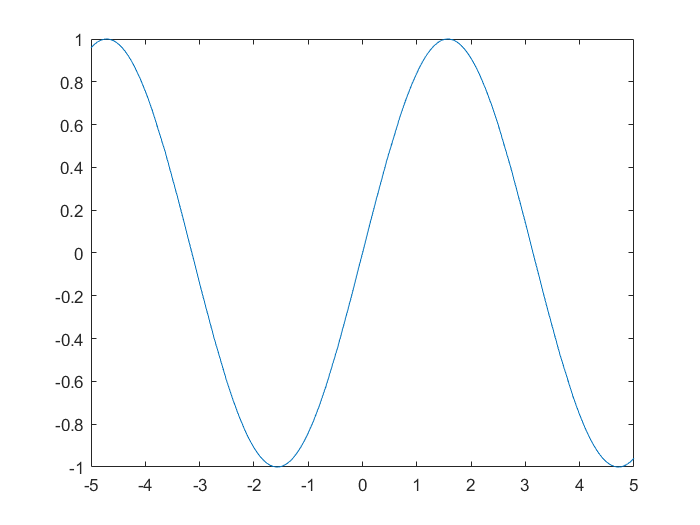

fplot(f)

Het x- en y-interval specifiëren gebeurt als volgt:

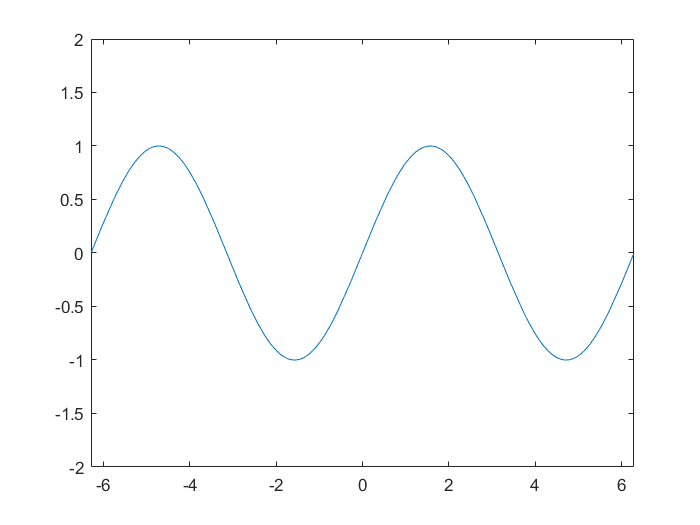

fplot(sin(x))
xlim([-2*pi, 2*pi])
ylim([-2, 2])

Als je met de muis over de grafiek beweegt, verschijnen er enkele opties om deze te bewerken, zoals verschuiven, zoomen, en herstellen naar de beginconfiguratie.

### Impliciet gedefinieerde functies

Voor een impliciet gedefinieerde kromme $f(x,y) = 0$ kun je het commando **fimplicit** gebruiken. Als je gewoon een funcie meegeeft, tekent dit de contourlijn $f(x,y) = 0$. Je kunt ook een vergelijking meegeven. Het domein specifieer je door eerst de grenzen van het interval voor x te geven, en dan voor y. Voor andere namen van variabelen is het alfabetisch.

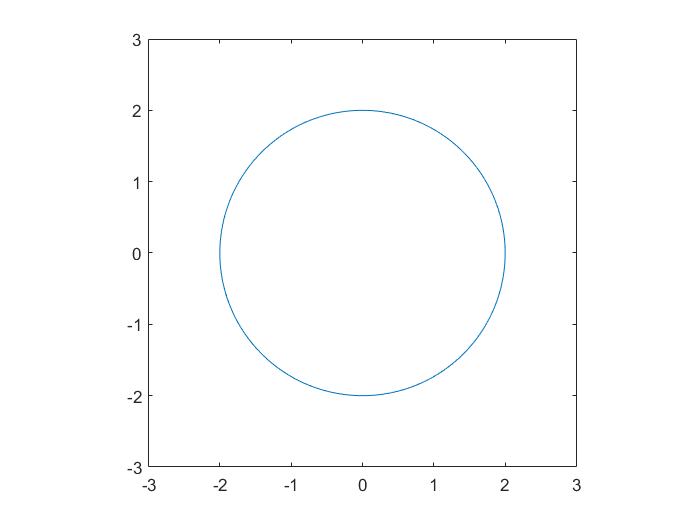

syms x y
fimplicit(x^2 + y^2 - 4, [-3, 3, -3, 3])
axis equal % gelijke schaling van de x- en y-as

## *3D-grafieken*

clear all
syms x y z t

### Krommen

Voor een geparametriseerde kromme in 3D gebruik je **fplot3**. 

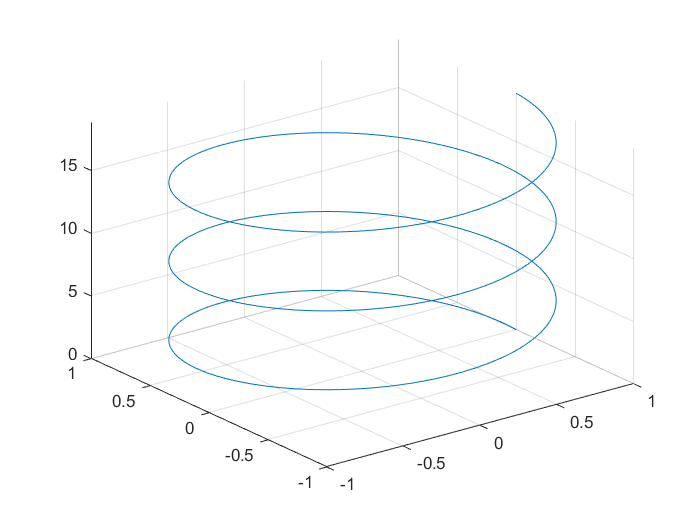

fplot3(cos(t), sin(t), t, [0, 6*pi] )

Als je met de muis over de grafiek te beweegt, verschijnt er een knop om de plot roteren door er met de muis over te slepen.

### Oppervlakken

Voor de grafiek van een functie in twee variabelen gebruik je **fsurf**. Het domein specifieer je door eerst de grenzen van het interval voor x te geven, en dan voor y.

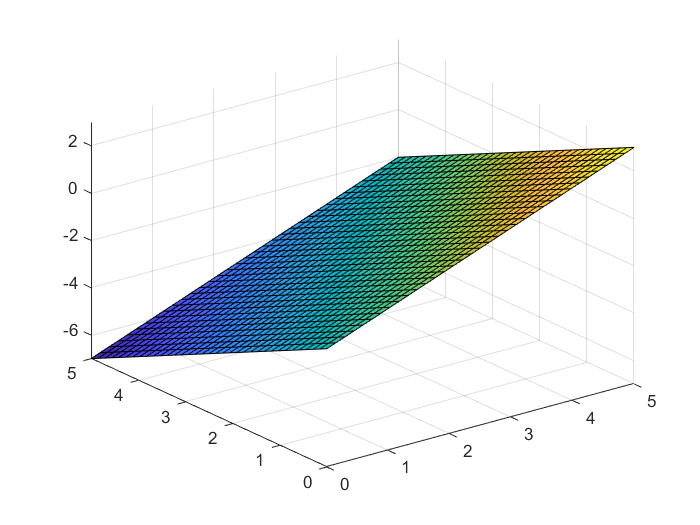

fsurf(x - y - 2, [0, 5, 0, 5])

Voor impliciet gedefineerde oppervlakken $f(x,y,z) = 0$ gebruik je **fimplicit3**. Zoals bij **fimplicit** kun je ofwel een functie ofwel een vergelijking meegeven.

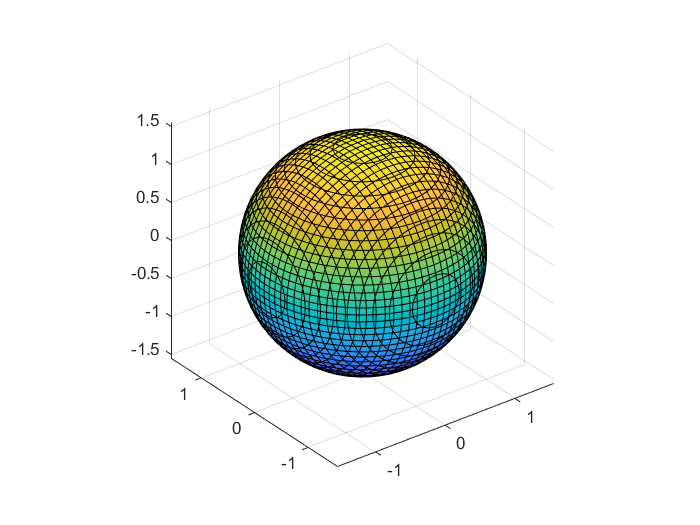

fimplicit3(x^2 + y^2 + z^2 - 2, [-2, 2, -2, 2, -2, 2])
axis equal

De nauwkeurigheid kun je aanpassen met **MeshDensity**.

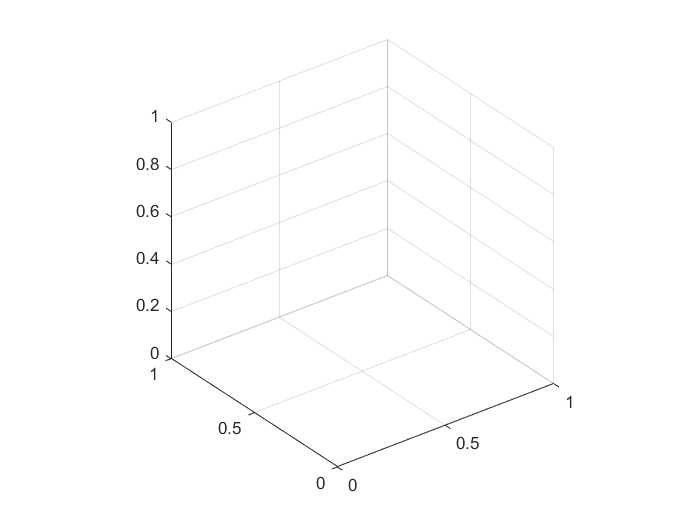

fimplicit3(x^2 + y^2 + z^2 - 2, [-2, 2, -2, 2, -2, 2], 'MeshDensity', 5)
axis equal

## *Contourplots*

clear all
syms x y
f(x, y) = x*y*(x^2 - y^2) / (x^2 + y^2)

$$f(x, y) = \frac{x\,y\,\left(x^{2}-y^{2}\right)}{x^{2}+y^{2}}$$

Voor contourplots hebben we het commando **fcontour**. De kleuren geven de niveaulijnen aan. Het commando **colorbar** geeft een legende voor de kleuren op de grafiek.

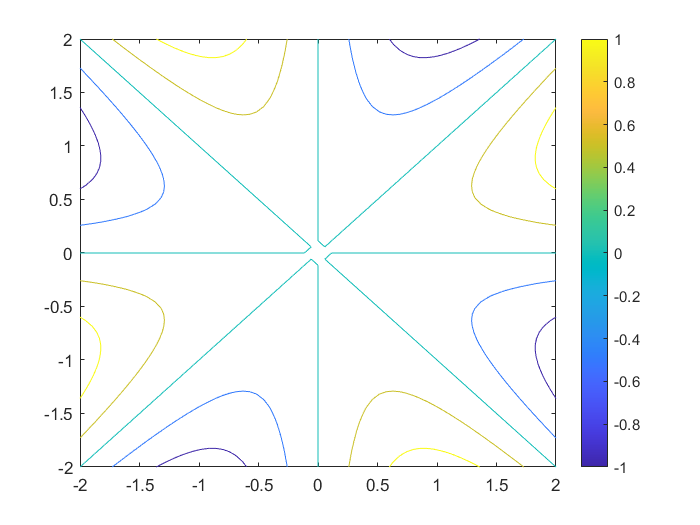

fcontour(f(x, y), [-2, 2, -2, 2])
colorbar

We kunnen het aantal weergegeven niveaus verhogen met de optie **LevelList**. Hoe meer waarden voor z we hieraan meegeven, hoe meer lijnen we zien op de figuur.

levels = linspace(-1, 1, 15) % 15 equidistante punten in [-1, 1] (op de z-as).

levels =    -1.0000   -0.8571   -0.7143   -0.5714   -0.4286   -0.2857   -0.1429         0    0.1429    0.2857    0.4286    0.5714    0.7143    0.8571    1.0000


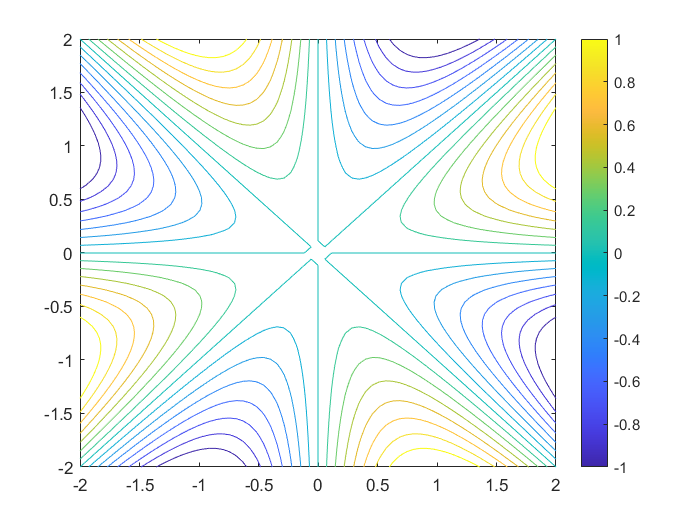

fcontour(f(x, y), [-2, 2, -2, 2], 'LevelList', levels)
colorbar

We kunnen de figuur inkleuren met **Fill**.

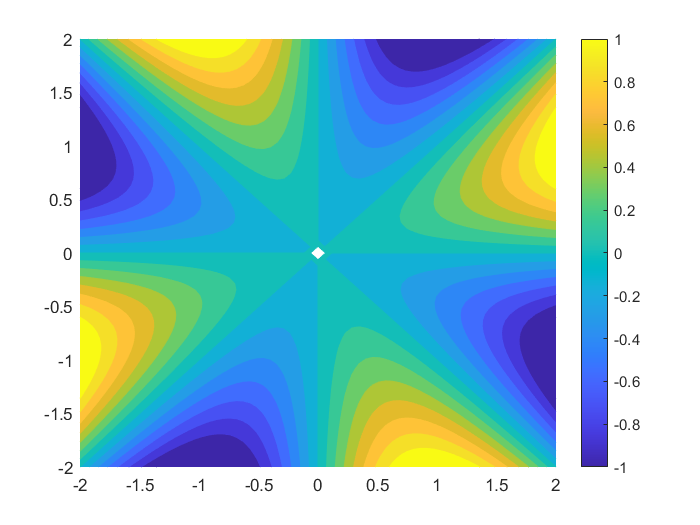

fcontour(f(x,y), [-2, 2, -2, 2], 'LevelList', levels, 'Fill', 'on')
colorbar

## *Numeriek berekende grafieken*

Soms volstaan de commando's voor plots van symbolische uitdrukkingen dan niet. Dan moet je de functie in op voorhand opgegeven punten evalueren, en een ander commando gebruiken om de grafiek door die punten te tekenen.

De punten om de functie in te evalueren genereer je met **linspace**. Dit geeft een vector met punten. **Let op: je moet component per component met deze vectoren rekenen en niet met vectoren als geheel (bijv. zoals bij het vectorproduct)!** Componentsgewijze vermenigvuldiging en deling doe je met **.* **en **./**, en machtsverheffing doe je met **.^**. De grafiek door deze punten teken je met het commando **plot**. 

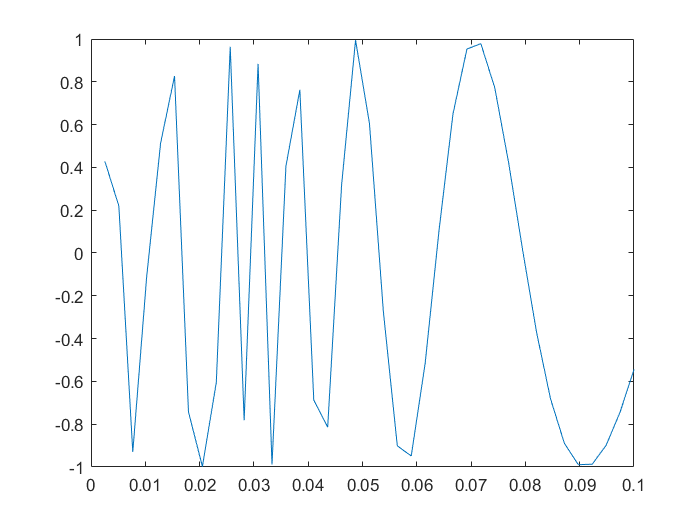

X = linspace(0, 0.1, 40); % genereert 40 equidistante punten in [0, 0.1]
Y = sin(1 ./ X);
plot(X, Y)

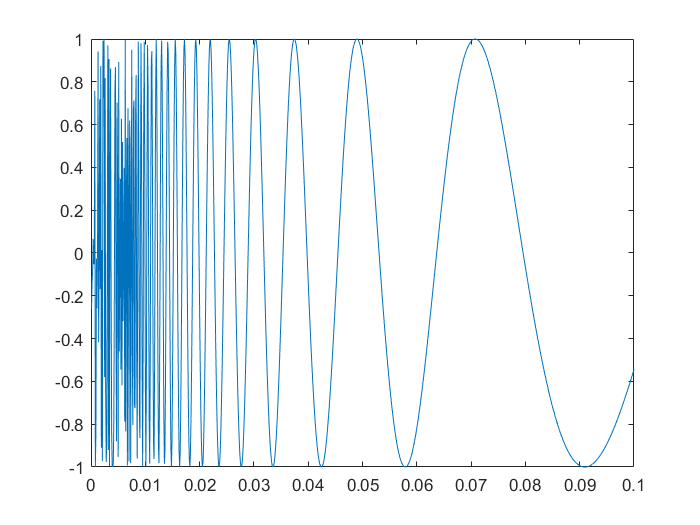

X = linspace(0, 0.1, 1000); % genereert 1000 equidistante punten in [0, 0.1]
Y = sin(1 ./ X);
plot(X, Y)

## *Vectorvelden*

Vectorvelden zul je ook moeten tekenen door eerst de evaluatiepunten mee te geven. Hier maken we onderscheid tussen verschillende gevallen.

### Vectorvelden in 2D

Om een vectorveld te tekenen, moet je zelf de punten specificeren waar je het vectorveld wilt evalueren. Deze geef je aan met de functies **linspace** en **meshgrid**.

x = linspace(-1, 1, 10)

x =    -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000


y = linspace(-1, 1, 10)

y =    -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000


[X, Y] = meshgrid(x, y)

X =    -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7778    1.0000
   -1.0000   -0.7778   -0.5556   -0.3333   -0.1111    0.1111    0.3333    0.5556    0.7

Y =    -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
   -0.7778   -0.7778   -0.7778   -0.7778   -0.7778   -0.7778   -0.7778   -0.7778   -0.7778   -0.7778
   -0.5556   -0.5556   -0.5556   -0.5556   -0.5556   -0.5556   -0.5556   -0.5556   -0.5556   -0.5556
   -0.3333   -0.3333   -0.3333   -0.3333   -0.3333   -0.3333   -0.3333   -0.3333   -0.3333   -0.3333
   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111   -0.1111
    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111    0.1111
    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333    0.3333
    0.5556    0.5556    0.5556    0.5556    0.5556    0.5556    0.5556    0.5556    0.5556    0.5556
    0.7778    0.7778    0.7778    0.7778    0.7778    0.7778    0.7778    0.7778    0.7778    0.7778
    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0

We definiëren een vectorveld in x en y. Daarna gebruiken we de functie **quiver** om het vectorveld te tekenen. Merk op dat we deze functie hier evalueren in de roosterpunten X en Y in plaats van de symbolische variabelen u en v. De eerste argumenten van **quiver** moeten steeds X en Y zijn, en dus niet een of andere parametrisatie.

syms u v
f(u, v) = -v;
g(u, v) = u;
F(u, v) = [f(u,v), g(u, v)]

$$F(u, v) = \left(\begin{array}{cc} -v & u \end{array}\right)$$

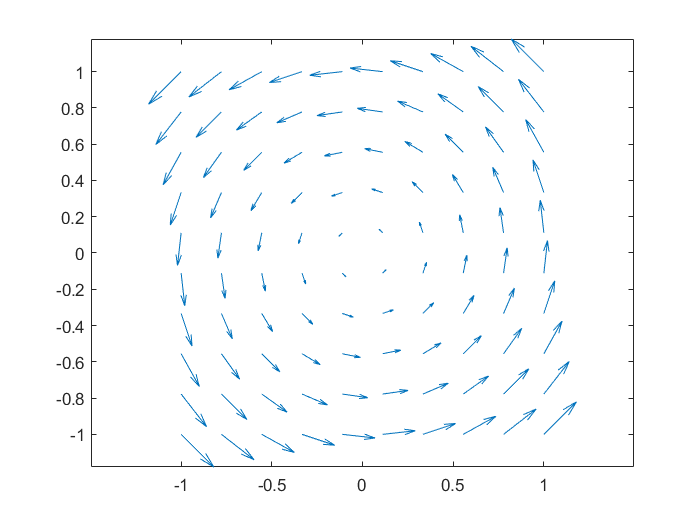

quiver(X, Y, f(X,Y), g(X, Y))
axis equal

### Vectorvelden in 3D

In drie dimensies is de procedure hetzelfde. Hier gebruiken we **quiver3** in plaats van **quiver**.

clear all
[X, Y, Z] = meshgrid(linspace(-1, 1, 6), linspace(-1, 1, 6), linspace(-2, 2, 6));
syms u v w
f(u,v,w) = -v / sqrt(u^2 + v^2 + w^2);
g(u,v,w) = u  / sqrt(u^2 + v^2 + w^2);
h(u,v,w) = u;
[f(u,v,w), g(u,v,w), h(u,v,w)]

$$ans = \left(\begin{array}{ccc} -\frac{v}{\sqrt{u^{2}+v^{2}+w^{2}}} & \frac{u}{\sqrt{u^{2}+v^{2}+w^{2}}} & u \end{array}\right)$$

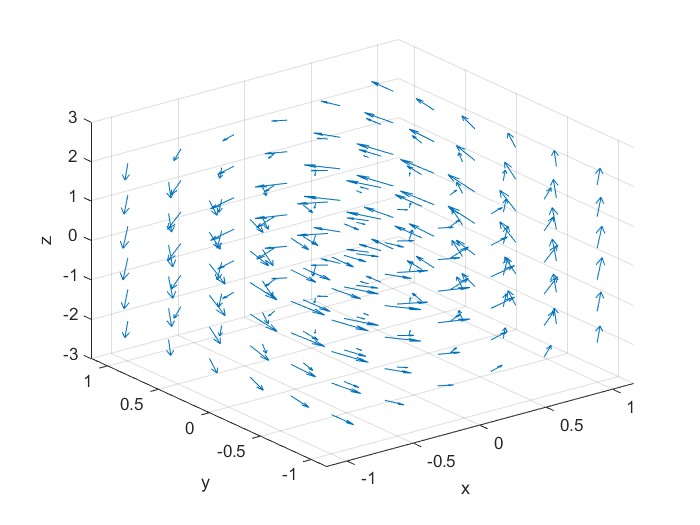

quiver3(X, Y, Z, f(X,Y,Z), g(X,Y,Z), h(X,Y,Z))
xlabel('x'); ylabel('y'); zlabel('z')

### Vectorvelden over een oppervlak

In veel toepassingen is het nuttig om een vectorveld over een oppervlak te tekenen. We gebruiken hier het oppervlak met parametrisatie $\Sigma = (x, y, f(x,y))$ met $f(x,y) = - (x^2 + y^2)$. Het vectorveld dat we tekenen, is de normaalvector op het oppervlak.

clear all
[X, Y]  = meshgrid(linspace(-1, 1, 10), linspace(-1, 1, 10));

We maken de functie f aan en evalueren die op het rooster. **OPGEPAST**: als we Z = X^2 - Y^2 schrijven, past MATLAB de matrixvermenigvuldiging toe. Hier willen we een componentsgewijze vermeningvuldiging. Dit kunnen we schrijven op twee manieren.

syms x y z
f(x, y) = - (x^2 + y^2);
Z = f(X, Y)

$$Z = \left(\begin{array}{cccccccccc} -2 & -\frac{130}{81} & -\frac{106}{81} & -\frac{10}{9} & -\frac{82}{81} & -\frac{82}{81} & -\frac{10}{9} & -\frac{106}{81} & -\frac{130}{81} & -2\\ -\frac{130}{81} & -\frac{98}{81} & -\frac{74}{81} & -\frac{58}{81} & -\frac{50}{81} & -\frac{50}{81} & -\frac{58}{81} & -\frac{74}{81} & -\frac{98}{81} & -\frac{130}{81}\\ -\frac{106}{81} & -\frac{74}{81} & -\frac{50}{81} & -\frac{34}{81} & -\frac{26}{81} & -\frac{26}{81} & -\frac{34}{81} & -\frac{50}{81} & -\frac{74}{81} & -\frac{106}{81}\\ -\frac{10}{9} & -\frac{58}{81} & -\frac{34}{81} & -\frac{2}{9} & -\frac{10}{81} & -\frac{10}{81} & -\frac{2}{9} & -\frac{34}{81} & -\frac{58}{81} & -\frac{10}{9}\\ -\frac{82}{81} & -\frac{50}{81} & -\frac{26}{81} & -\frac{10}{81} & -\frac{2}{81} & -\frac{2}{81} & -\frac{10}{81} & -\frac{26}{81} & -\frac{50}{81} & -\frac{82}{81}\\ -\frac{82}{81} & -\frac{50}{81} & -\frac{26}{81} & -\frac{10}{81} & -\frac{2}{81} & -\frac{2}{81} & -\frac{10}{81} & -\frac{26}{81} & -\frac{50}{81} & -\frac{82}{81}\\ -\frac{10}{9} & -\frac{58}{81} & -\frac{34}{81} & -\frac{2}{9} & -\frac{10}{81} & -\frac{10}{81} & -\frac{2}{9} & -\frac{34}{81} & -\frac{58}{81} & -\frac{10}{9}\\ -\frac{106}{81} & -\frac{74}{81} & -\frac{50}{81} & -\frac{34}{81} & -\frac{26}{81} & -\frac{26}{81} & -\frac{34}{81} & -\frac{50}{81} & -\frac{74}{81} & -\frac{106}{81}\\ -\frac{130}{81} & -\frac{98}{81} & -\frac{74}{81} & -\frac{58}{81} & -\frac{50}{81} & -\frac{50}{81} & -\frac{58}{81} & -\frac{74}{81} & -\frac{98}{81} & -\frac{130}{81}\\ -2 & -\frac{130}{81} & -\frac{106}{81} & -\frac{10}{9} & -\frac{82}{81} & -\frac{82}{81} & -\frac{10}{9} & -\frac{106}{81} & -\frac{130}{81} & -2 \end{array}\right)$$

Z2 = - (X.^2 + Y.^2);

We definieren het vectorveld en de drie coördinaatsfuncties.

Sigma = [x, y, f(x,y)];
vectorveld = cross(diff(Sigma, x), diff(Sigma, y))

$$vectorveld = \left(\begin{array}{ccc} 2\,x & 2\,y & 1 \end{array}\right)$$

P(x,y,z) = vectorveld(1);
Q(x,y,z) = vectorveld(2);
R(x,y,z) = vectorveld(3);

Hiermee kunnen we de grafiek tekenen.

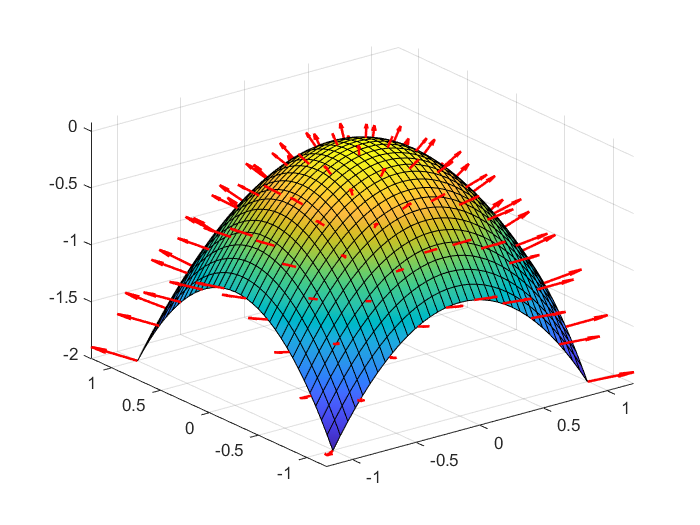

fsurf(f(x,y), [-1, 1, -1, 1])
hold on
quiver3(X, Y, Z, P(X,Y,Z), Q(X,Y,Z), R(X,Y,Z), 'red', 'LineWidth', 1.5)
hold off

## *Andere nuttige commando's*

### Meerdere plots op dezelfde figuur

clear all
syms x y

Het is eveneens mogelijk om verschillende grafieken tegelijk te maken met **fplot** en **fsurf**. Dit doe je door de functies tussen haakjes [] te plaatsen. De legende voegen we achteraf toe met het commando **legend**.

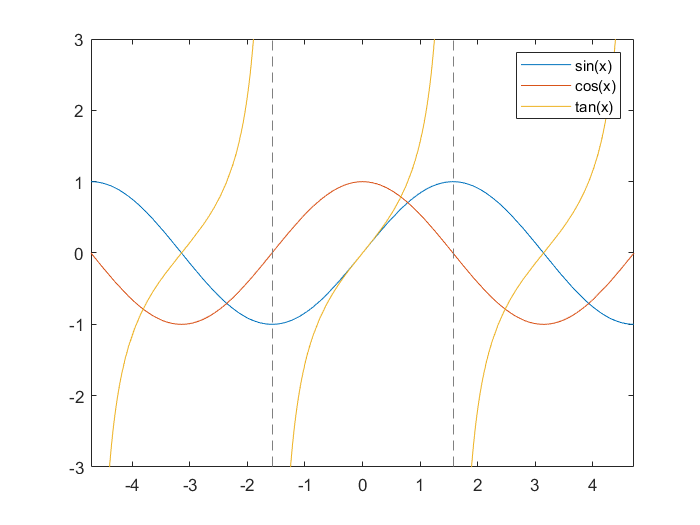

fplot([sin(x), cos(x), tan(x)], [-1.5*pi, 1.5*pi])
ylim([-3, 3])
legend('sin(x)', 'cos(x)', 'tan(x)')

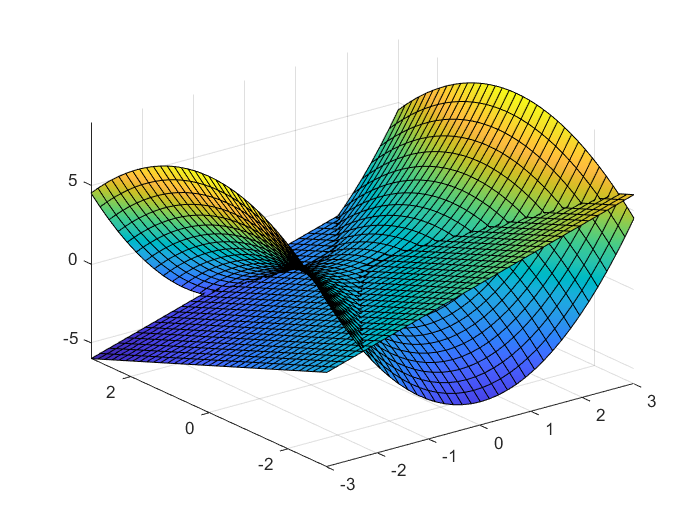

fsurf([x - y, x^2 - 1/2*y^2], [-3, 3, -3, 3])

Een andere mogelijkheid is elke grafiek apart te tekenen, waarbij we met het commando **hold** aangeven dat deze op dezelfde figuur komen. Het commando **figure** geeft aan dat we een nieuwe figuur beginnen. Als we dit niet gebruiken, zorgt **hold **ervoor dat we de grafiek bovenop de vorige tekenen.

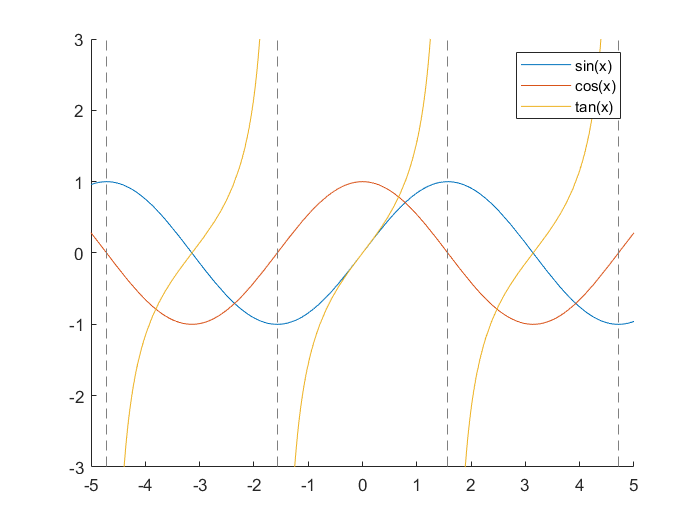

figure()
hold on
fplot(sin(x))
fplot(cos(x))
fplot(tan(x))
ylim([-3, 3])
legend('sin(x)', 'cos(x)', 'tan(x)')
hold off

### Opmaak

Er zijn veel opties om het uitzicht van grafieken te veranderen. Hier volgen enkele voorbeelden.

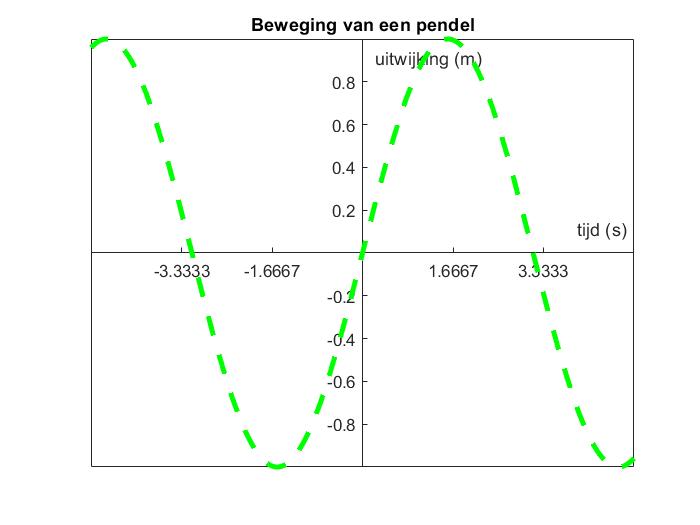

fplot(sin(x), '--', 'color', 'green', 'linewidth', 3)
title('Beweging van een pendel')
xlabel('tijd (s)')
ylabel('uitwijking (m)')
xticks(linspace(-5, 5, 7))
set(gca, 'XAxisLocation', 'origin')
set(gca, 'YAxisLocation', 'origin')

## **6. Een beetje programmeren**

Matlab Live Scripts hebben een aantal structuren om te programmeren.

## ***If-then-else***

**if** <voorwaarde> 

    <bewerkingen>  

**end** 

Als aan <voorwaarde> voldaan is, worden <bewerkingen> uitgevoerd. Als aan <voorwaarde> niet voldaan is, gebeurt er niets.

x = sym(-3)

$$x = -3$$

if x < 0
    y = x + sym(2);
    x = -x;
    x, y
end

$$x = 3$$

$$y = -1$$

**if** <voorwaarde>  

    <bewerkingen>  

**else** 

    <andere bewerkingen>  

**end** 

Als aan <voorwaarde> voldaan is, worden <bewerkingen> uitgevoerd. Als aan <voorwaarde> niet voldaan is, worden <andere bewerkingen> uitgevoerd.

x = 6

x = 6

if x < 0
    y = x + sym(2);
    x = -x;
    disp([x, y])
else
    y = x + sym(2);
    x = x;
    disp([x, y])
end

$$\left(\begin{array}{cc} 6 & 8 \end{array}\right)$$

Meerdere voorwaarden worden gecombineerd met & (en), | (of).

x = 4;
if x >= 0 & symFunType(sym(x)) == "integer"
    disp('x is a positive integer')
end

x is a positive integer


De bewerkingen van het then of else gedeelte mogen terug  **if ... then ... else ... end_if** zijn. Daarbij kan  **else if** afgekort worden tot  **elif** .

x = sym(2);
if isSymType(x, 'complex') == true
    disp('The Heaviside function is not defined for complex numbers')
else
    if x == sym(0)
        heavisideX = sym(1/2)
    else
        if x < 0
            heavisideX = sym(0)
        else
            heavisideX = sym(1)
        end
    end
end

$$heavisideX = 1$$


x = sym(0);
if isSymType(x, 'complex') == true
    disp('The Heaviside function is not defined for complex numbers')
else
    if x == sym(0)
        heavisideX = sym(1/2)
    else
        if x < 0
            heavisideX = sym(0)
        else
            heavisideX = sym(1)
        end
    end
end

$$heavisideX = \frac{1}{2}$$

## *For-lussen*

Een bewerking een op voorhand vastgelegd aantal keer laten uitvoeren, kan met een for-lus:

**for** <i>  **=** <startwaarde>  **: **<stapgrootte> **:** <stopwaarde>

    <bewerkingen>  

**end**

als <stapgrootte> gelijk aan 1 is, moet die niet vermeld worden.

for j = 1 : 3
    a = j;
    b = j^2;
    a, b
end

a = 1

b = 1

a = 2

b = 4

a = 3

b = 9

De laatste waarde van j wordt bewaard na de laatste stap en kan eventueel verder gebruikt worden.

j

j = 3

<stapgrootte> is niet noodzakelijk een geheel getal.

for j = 2.2:-.5:1
    j
end

j = 2.2000

j = 1.7000

j = 1.2000

j

j = 1.2000

## *While-lussen*

**while** <voorwaarde>  

    <bewerkingen>  

**end** 

zolang aan <voorwaarde> voldaan is, wordt <bewerkingen> uitgevoerd. De <bewerkingen> hebben dus invloed op <voorwaarde>. Let op voor oneindige lussen!

<voorwaarde> wordt getest voor de bewerkingen worden uitgevoerd.

j = 1;
s = 0;
while j <= 4
    s = s + j;
    disp(s)
    j = j + 1;
end

     1

     3

     6

    10

